# Attitude control example

## note

NA

## references 

## revisions

20241213  y.yoshimura, y.yoshimula@gmail.com

See also .

clc
clear


## to be set

deired attitude angle in terms of 3-2-1 Euler angles $(\phi \rightarrow \theta \rightarrow \psi)$

para.phiD = [deg2rad(0); deg2rad(0); deg2rad(0)]; % desired attitude (phi, theta, psi)

% moment of inertia
para.MOI = diag([10, 14, 20]);

## solve ODE

% initial condition
eulerIni = rand(1,3);
wIni = rand(1,3);

tspan = 0:1:60;
opts = odeset('RelTol',1e-8,'AbsTol',1e-8);
[t_, x_] = ode45(@(t,x) eomAtti321(t, x, para), tspan, [eulerIni, wIni], opts);



### data handling & show figures

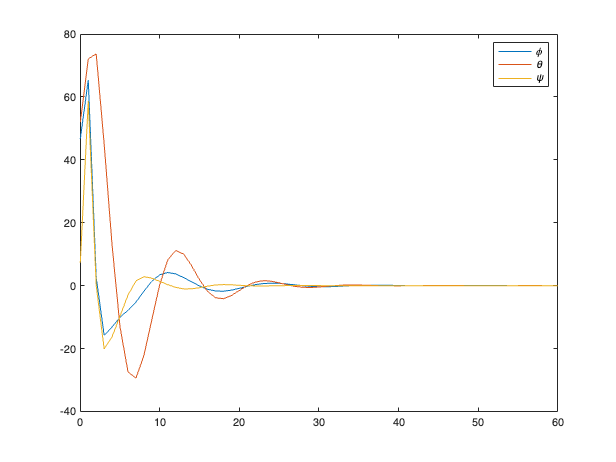

phi = x_(:,1);
theta = x_(:,2);
psi = x_(:,3);
wx = x_(:,4);
wy = x_(:,5);
wz = x_(:,6);


figure
plot(t_, rad2deg(phi), t_, rad2deg(theta), t_, rad2deg(psi))
legend('\phi','\theta', '\psi')

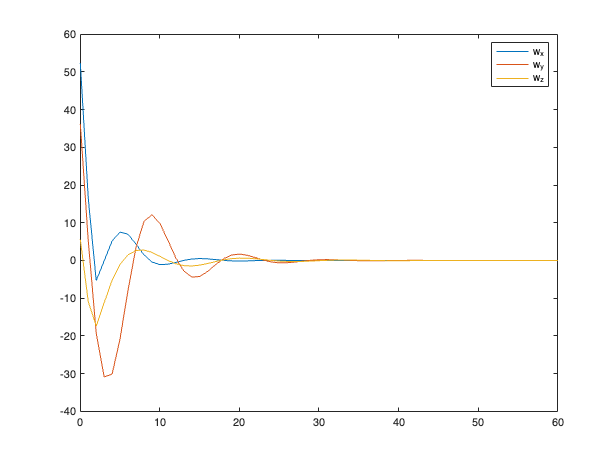



figure
plot(t_, rad2deg(wx), t_, rad2deg(wy), t_, rad2deg(wz))
legend('w_x','w_y', 'w_z')